# 10. Arrays

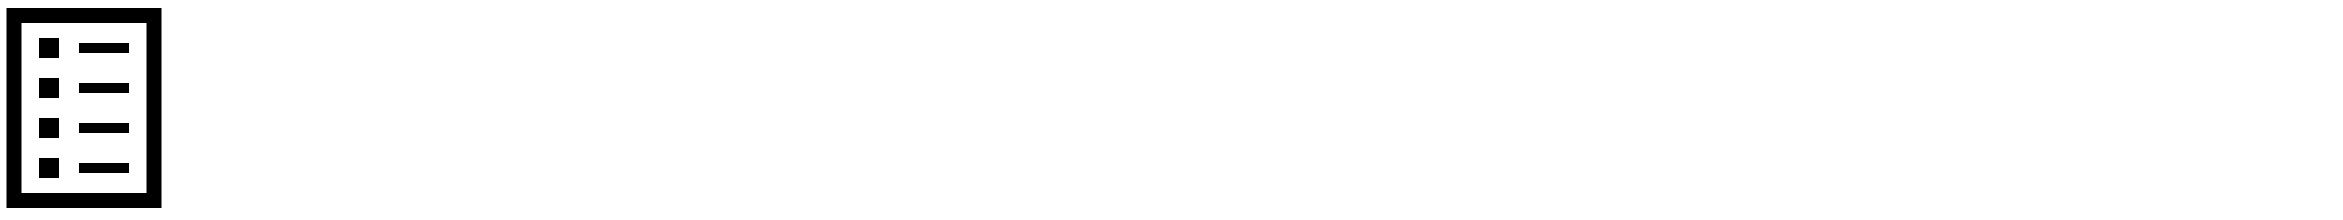

Arrays are a way of storing a sequence of numbers or letters.

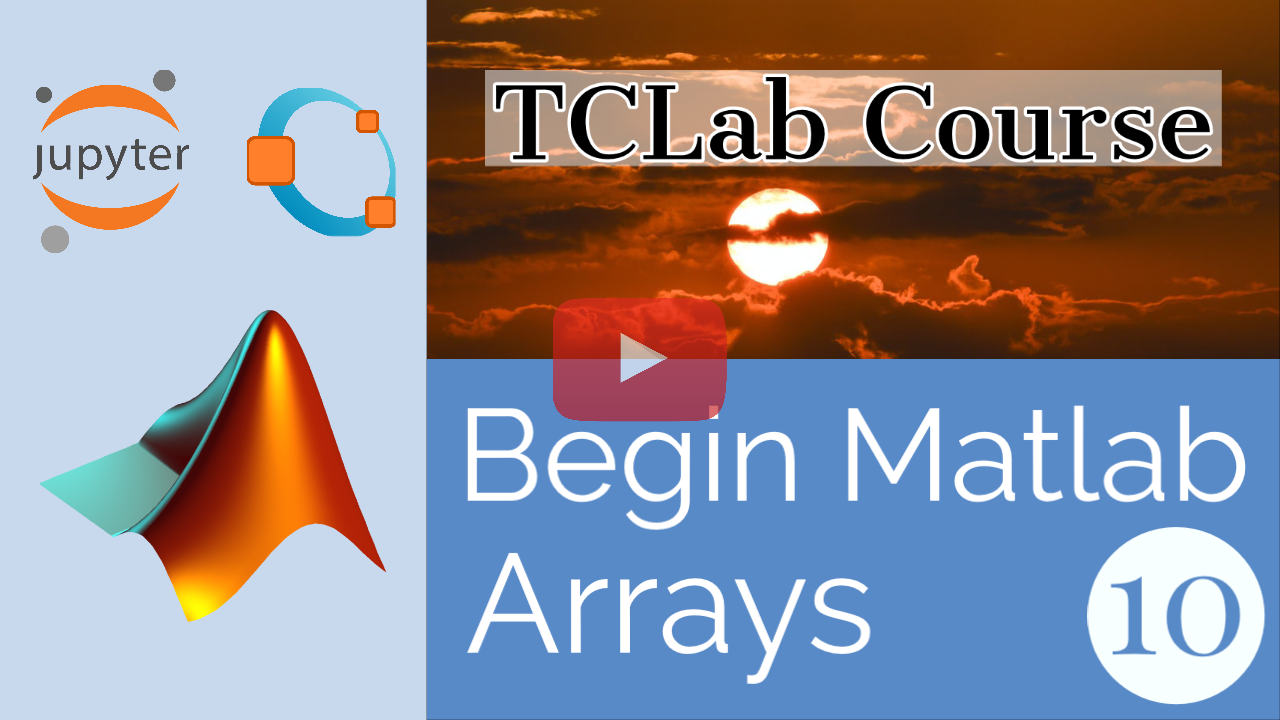

[Click here to watch the video: Matlab 👩‍💻 Array and Matrix](https://www.youtube.com/watch?v=aBhyAar5hcQ&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

This is shown below, by using brackets [ ]. You could use an array for an incubator to keep information on such as a history of the temperatures.

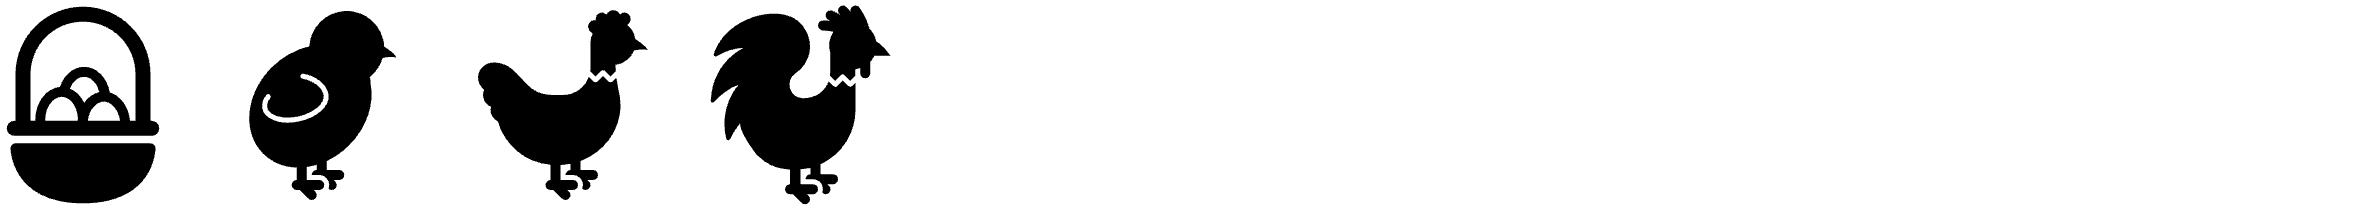

% array of numbers
history = [37.1, 37.2, 37.0, 36.9, 37.1]

You can change one of the values in an array, use just one value with `history(2)`, or a range of values with `history(2:4)`. A list index starts at `1`.

history(2)
history(2:4)

You can also use an array inside a `for` loop. Use parenthesis with the number or range to access values of the array.

history = [37.1,37.2,37.3];
for i = 1:length(history)
    disp(history(i))
end

You can even do a `for` loop to access the values of an array with `if` statements inside. The `==` symbol is comparing two values. If they are the same it will be `true`.

history = [37.1,37.2,37.3];
for i = 1:length(history)
    history(i)
    if history(i)==37.2
        disp('middle temperature')
    end
end

### **Insert Values**

It is possible to remove or insert values into an array. The `end` is the last element of an array. The array size expands as you add elements to the end such as history(end+1) = 37.6.

h = [1,2,3]
h(end+1) = 4

You can also remove an element(s) by defining a new array without that element such as `[h(1),h(3:end)]` to remove the second element.

h = [h(1),h(3:end)]

You can also insert values into the middle of an array.

h = [h(1:2),2,h(3:end)]

### **Assigning New Values**

After you get all of your data points in a list, one way to execute the same equation to all values in a list is shown below. This can be very useful, for example if you wanted to turn your data points from Celsius to Fahrenheit. The example below shows a way to convert a whole list of values from Celsius to Fahrenheit.

data_celsius = [24, 21, 26, 30, 20] % List of Celsius temperature values

data_fahrenheit = data_celsius*(9/5) + 32  % This converts to Fahrenheit

### Activity

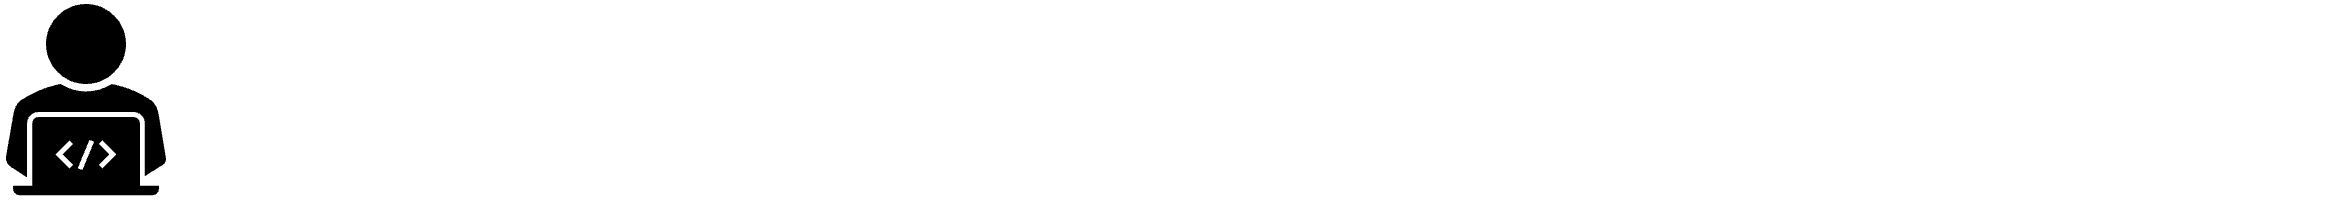

Use user input to add temperature values to an array. One temperature value is collected each second for 20 seconds. If you see an error `You already have an open connection` then `clear all` or unplug and reconnect the Arduino.

clear all
lab = tclab;

% initialize lists
tm = []
T1 = []

% turn on heater 1
lab.Q1(60)

for i = 1:20
    tm(end+1) = i;
    disp([i,': ', lab.T1])
    % store the new temperature in the array T1

    pause(3)
end

disp(T1)
lab.off(); clear lab

Make a `for` loop that uses at least **5 values**, stored in an array, of your choice to turn on the **LED light** and **both heaters**. It should end with **0** to make sure the light **and** heaters are off.

Make sure there is a **3 second** break in between each light and heater change, and print out the temperatures from the heaters every time the program loops.

myArray = ["5 different numbers", 0] % Put 5 numbers in this list between 0 and 100.
                                     % The last one should be zero.